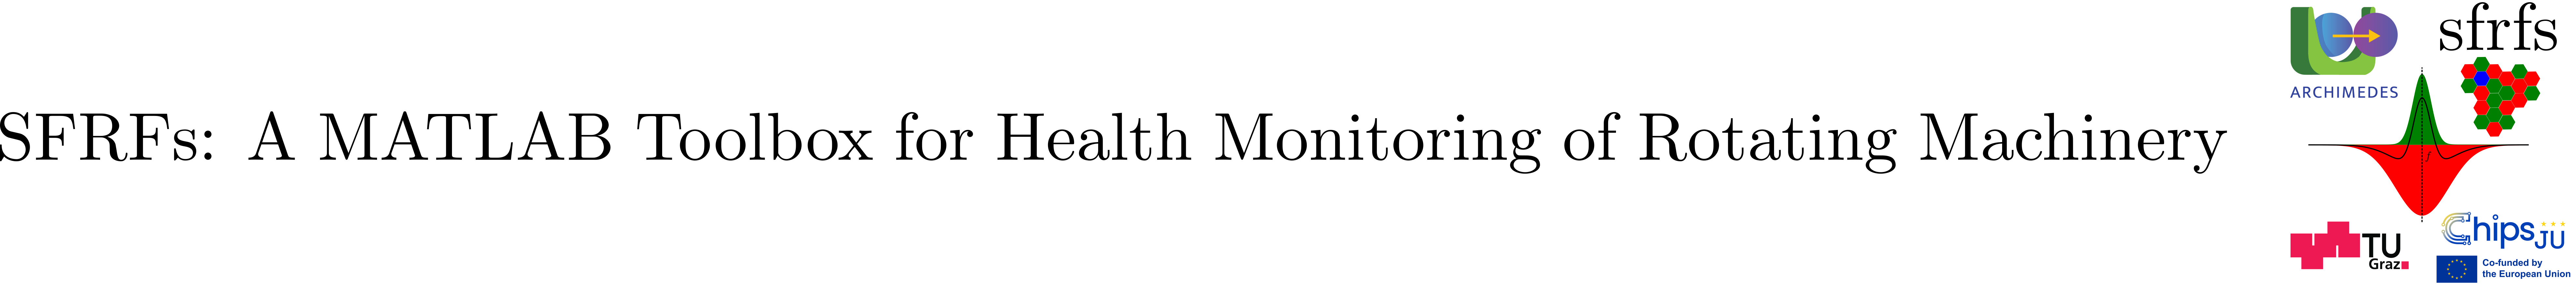

# OnOffContrastPolarityDetector

## Summary

`OnOffContrastPolarityDetector` is a static utility class that detects signed ON and OFF events in harmonic-indexed contrast trajectories. It identifies transitions between zero and nonzero contrast activity while preserving the polarity associated with each event.

**Key features:**

- Detects ON events when harmonic contrast changes from zero to nonzero.

- Detects OFF events when harmonic contrast changes from nonzero to zero.

- Preserves the polarity of the newly active contrast for ON events and the previously active contrast for OFF events.

- Processes individual observation transitions and complete harmonic contrast trajectories.

- Produces separate signed ON and OFF event maps.

- Reports positive and negative ON/OFF event counts for each harmonic.

- Validates contrast trajectories and observation indices.

The class implements the harmonic contrast polarity ON/OFF event operators described in Algorithm 3 of the contrast polarity analysis framework presented in [3].

## Description

`OnOffContrastPolarityDetector` provides static methods for detecting the appearance and disappearance of nonzero harmonic contrast activity, distinguishing positive and negative polarity events.

For each harmonic, an ON event occurs when the contrast changes from zero to nonzero between consecutive observations. The event is assigned the polarity of the newly active contrast. An OFF event occurs when the contrast changes from nonzero to zero and retains the polarity of the previously active contrast.

Direct transitions between positive and negative nonzero contrasts are not classified as ON or OFF events. Such transitions are handled separately by `PolarityReversalDetector`. The first observation does not generate events because no preceding observation is available for comparison.

The `detect` method evaluates the transition between two consecutive contrast snapshots at a specified observation index and returns separate signed ON and OFF event vectors.

The `detectAll` method processes an entire harmonic contrast trajectory, with observations arranged in rows and harmonics in columns. It returns two signed event matrices identifying the observation and harmonic associated with each ON or OFF event.

The `summarize` method extends trajectory-wide detection by computing positive and negative ON and OFF event counts independently for each harmonic.

The class is a stateless utility operating on signed contrast trajectories. It does not compute receptive-field responses, center–surround contrast, or cross-sensor agreement and may be applied downstream of `ContrastPolarityFilter` or independently to other signed contrast representations.

**See also:** [`PolarityReversalDetector`](matlab:open('./PolarityReversalDetector.mlx')), [`ContrastPolarityFilter`](matlab:open('./ContrastPolarityFilter.mlx')), [`ContrastMappings`](matlab:open('./ContrastMappings.mlx')).

## Public methods

### detect

Detects signed ON and OFF events in harmonic-indexed contrast responses at a specified observation.

For each harmonic, the method compares the contrast at the current observation with that of the immediately preceding observation. An ON event occurs when a previously zero-valued contrast becomes nonzero, while an OFF event occurs when a previously nonzero contrast becomes zero.

ON events retain the polarity of the newly active contrast, whereas OFF events retain the polarity of the previously active contrast. Direct transitions between nonzero contrasts do not produce ON or OFF events, regardless of polarity.

At the first observation, both event vectors are zero because no preceding observation is available.

#### Syntax

`[eOn, eOff] = OnOffContrastPolarityDetector.detect(C, t);`

#### Parameters

For $t>1$, let $c_{t,h}$ denote the signed contrast of harmonic $h$ at observation $t$, and define


$$u_{t,h}=\mathrm{sign}(c_{t,h}).$$


An ON event is generated when the previous polarity is zero and the current polarity is nonzero:


$$(u_{t-1,h}=0 \land u_{t,h}\neq 0)
\Rightarrow e^{\mathrm{on}}_{t,h}=u_{t,h}$$


An OFF event is generated when the previous polarity is nonzero and the current polarity is zero:


$$(u_{t-1,h}\neq 0 \land u_{t,h}=0)
\Rightarrow e_{t,h}^{\mathrm{off}}=u_{t-1,h}$$


For the first observation, both event representations are initialized to zero:


$$e^{\mathrm{on}}_{1,h}=e^{\mathrm{off}}_{1,h}=0
$$


These expressions preserve event polarity and distinguish activity transitions from direct nonzero polarity reversals, which are handled separately by `PolarityReversalDetector`.

The method does not maintain internal temporal state; it accesses the current and preceding observations directly from `C`.

### detectAll

Detects signed ON and OFF events over a complete harmonic-indexed contrast trajectory.

The method processes consecutive observations in chronological order, independently identifying transitions between zero and nonzero contrast activity for each harmonic. ON events preserve the polarity of the newly active contrast, while OFF events preserve the polarity of the previously active contrast.

Unlike `detect`, which evaluates a specified observation, `detectAll` evaluates the complete trajectory and returns two signed event matrices. Both matrices contain zeros in their first row because no preceding observation is available.

#### Syntax

`[onMap, offMap] = OnOffContrastPolarityDetector.detectAll(C);`

#### Parameters

#### Output

For a contrast trajectory $C\in\mathbb{R}^{T\times H}$, both event maps have dimensions $T\times H$. The method evaluates `detect(C, t)` for every observation index $t\in\{1,\ldots,T\}$, storing the resulting signed event vectors in their corresponding rows.

Each harmonic is processed independently. Direct changes between opposite nonzero polarities produce neither ON nor OFF events, while transitions between zero and nonzero contrast produce the corresponding signed event.

The method does not retain temporal state internally or return event counts. For per-harmonic event statistics, use `summarize`.

### summarize

Summarizes positive and negative ON and OFF events over a complete harmonic-indexed contrast trajectory.

The method computes signed ON and OFF event maps using `detectAll`, then counts the occurrences of positive and negative events independently for each harmonic.

The resulting summary preserves both event maps and distinguishes four event categories: positive ON, negative ON, positive OFF, and negative OFF.

#### Syntax

`summary = OnOffContrastPolarityDetector.summarize(C);`

#### Parameters

#### Output

Returns a structure `summary` containing:

For a contrast trajectory with $T$ observations and $H$harmonics, let $E^{\mathrm{on}}, E^{\mathrm{off}} \in \{-1,0,1\}^{T\times H}$ denote the signed event maps.

The positive and negative ON-event counts are


$$N_h^{\mathrm{on},+} = \sum_{t=1}^{T} [E_{t,h}^{\mathrm{on}} > 0]$$



$$N_h^{\mathrm{on},-} = \sum_{t=1}^{T} [E_{t,h}^{\mathrm{on}} < 0]$$


Similarly, the positive and negative OFF-event counts are


$$N_h^{\mathrm{off},+} = \sum_{t=1}^{T} [E_{t,h}^{\mathrm{off}} > 0]$$



$$N_h^{\mathrm{off},-} = \sum_{t=1}^{T} [E_{t,h}^{\mathrm{off}} < 0]$$


Here, square brackets denote the indicator of the enclosed condition, equal to one when the condition holds and zero otherwise.

The method returns absolute event counts rather than event rates. ON and OFF event counts are computed independently, and the signed event maps are retained in the output structure for further analysis.

## Example

This example illustrates the detection of signed ON and OFF events in harmonic-indexed contrast trajectories. We use the same deterministic six-harmonic, 24-observation trajectory introduced in the `PolarityReversalDetector` example, allowing direct comparison between polarity activity transitions and polarity reversals.

The experiment demonstrates all three public methods: `detect`, `detectAll`, and `summarize`. Positive and negative ON/OFF events are distinguished by their associated contrast polarities.

### Synthetic harmonic contrast trajectory

The six harmonic channels exhibit persistent activity, direct polarity reversals, temporary disappearance and reappearance of contrast, and delayed activation. Only transitions between zero and nonzero contrast produce ON or OFF events.

% Configure the synthetic experiment
nObservations = 24;
nHarmonics = 6;

C = zeros(nObservations, nHarmonics);

% Harmonic 1: persistent positive polarity followed by deactivation
C(1:18, 1) = 2;

% Harmonic 2: direct positive-to-negative reversal
C(1:12, 2) = 1.5;
C(13:end, 2) = -1.5;

% Harmonic 3: negative, then zero, then positive
C(1:8, 3) = -2;
C(13:end, 3) = 2;

% Harmonic 4: two direct polarity reversals
C(1:8, 4) = 1;
C(9:16, 4) = -1;
C(17:end, 4) = 1;

% Harmonic 5: intermittent zeros, always negative when active
C(:, 5) = -1.5;
C(7:10, 5) = 0;
C(17:20, 5) = 0;

% Harmonic 6: delayed activation followed by reversal
C(9:16, 6) = 2;
C(17:end, 6) = -2;

### Detecting and summarizing ON/OFF events

We first apply `detect` at every observation and construct signed event maps. We then verify that these agree with the outputs of `detectAll` and obtain the per-harmonic event counts using `summarize`.

% Sequential ON/OFF event detection
sequentialOn = zeros(size(C));
sequentialOff = zeros(size(C));

for t = 1:nObservations
    [sequentialOn(t, :), sequentialOff(t, :)] = ...
        OnOffContrastPolarityDetector.detect(C, t);
end

% Trajectory-wide signed event maps
[onMap, offMap] = ...
    OnOffContrastPolarityDetector.detectAll(C);

% Verify equivalence of the two interfaces
assert(isequal(sequentialOn, onMap));
assert(isequal(sequentialOff, offMap));

% Summarize positive and negative events
summary = OnOffContrastPolarityDetector.summarize(C);

results = table( ...
    (1:nHarmonics).', ...
    summary.PositiveOnCountPerHarmonic, ...
    summary.NegativeOnCountPerHarmonic, ...
    summary.PositiveOffCountPerHarmonic, ...
    summary.NegativeOffCountPerHarmonic, ...
    VariableNames = { ...
    'HarmonicIndex', ...
    'PositiveOn', 'NegativeOn', ...
    'PositiveOff', 'NegativeOff'});

disp(results);

    HarmonicIndex    PositiveOn    NegativeOn    PositiveOff    NegativeOff
    _____________    __________    __________    ___________    ___________

          1              0             0              1              0     
          2              0             0              0              0     
          3              1             0              0              1     
          4              0             0              0              0     
          5              0             2              0              2     
          6              1             0              0              0     



Notice that harmonic 2 changes directly from positive to negative without producing an ON or OFF event, while harmonic 3 produces a negative OFF event followed by a positive ON event.

### Visualizing signed ON/OFF events

We retain the soft diverging contrast colormap used in `PolarityReversalDetector`, overlaying circles for ON events and crosses for OFF events. The event polarity is distinguished by blue (negative) and red (positive) markers.

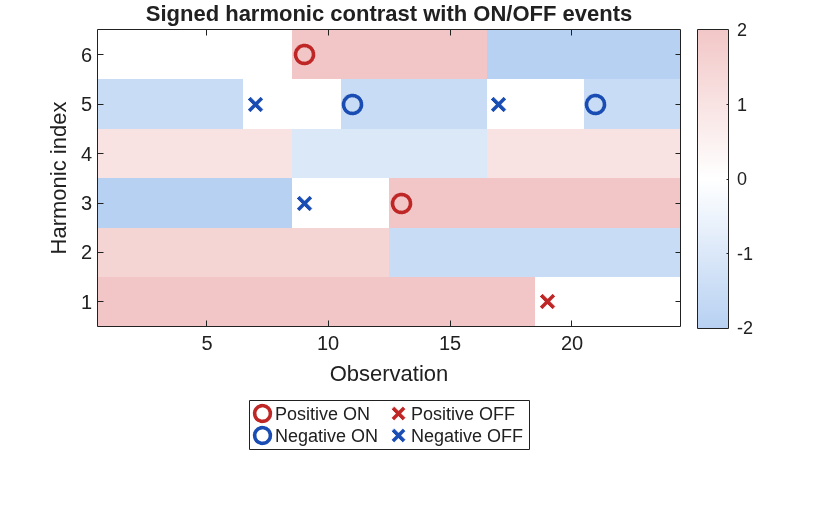

figure;
ax = axes;

% Soft diverging colormap
n = 256;
m = n/2;
blue = [0.72 0.82 0.95];
white = [1.00 1.00 1.00];
red = [0.95 0.78 0.78];

cmapNeg = [ ...
    linspace(blue(1), white(1), m).' ...
    linspace(blue(2), white(2), m).' ...
    linspace(blue(3), white(3), m).' ];

cmapPos = [ ...
    linspace(white(1), red(1), m).' ...
    linspace(white(2), red(2), m).' ...
    linspace(white(3), red(3), m).' ];

softMap = [cmapNeg; cmapPos];

% Signed contrast trajectory
imagesc(ax, C.');
set(ax, YDir="normal");
colormap(ax, softMap);
clim(ax, [-max(abs(C(:))), max(abs(C(:)))]);
colorbar(ax);

xlabel(ax, 'Observation');
ylabel(ax, 'Harmonic index');
title(ax, 'Signed harmonic contrast with ON/OFF events');
yticks(ax, 1:nHarmonics);

hold(ax, 'on');

% Event masks and positions
[tOnPos, hOnPos] = find(onMap > 0);
[tOnNeg, hOnNeg] = find(onMap < 0);
[tOffPos, hOffPos] = find(offMap > 0);
[tOffNeg, hOffNeg] = find(offMap < 0);


% Positive and negative ON events: circles
hOnPos = plot(ax, tOnPos, hOnPos, 'o', ...
    Color=[0.75 0.15 0.15], MarkerSize=9, LineWidth=1.8);
hOnNeg = plot(ax, tOnNeg, hOnNeg, 'o', ...
    Color=[0.10 0.30 0.70], MarkerSize=9, LineWidth=1.8);

% Positive and negative OFF events: crosses
hOffPos = plot(ax, tOffPos, hOffPos, 'x', ...
    Color=[0.75 0.15 0.15], MarkerSize=9, LineWidth=1.8);
hOffNeg = plot(ax, tOffNeg, hOffNeg, 'x', ...
    Color=[0.10 0.30 0.70], MarkerSize=9, LineWidth=1.8);

legend(ax, [hOnPos, hOnNeg, hOffPos, hOffNeg], ...
    {'Positive ON', 'Negative ON', 'Positive OFF', 'Negative OFF'}, ...
    Location='southoutside', NumColumns=2);

hold(ax, 'off');

## API documentation

The class provides built-in MATLAB help and a Live Script reference documenting its public methods, signed event semantics, and examples.

help OnOffContrastPolarityDetector

 OnOffContrastPolarityDetector Detect signed contrast polarity ON/OFF events.
 
  Detects transitions between zero and nonzero harmonic contrasts,
  preserving the polarity of the newly active or previously active
  response in the corresponding ON or OFF event.
 
  Provides snapshot-wise detection, trajectory-wide signed event maps,
  and per-harmonic positive and negative event counts.

    Documentation for OnOffContrastPolarityDetector



doc OnOffContrastPolarityDetector

## Source code

The MATLAB implementation can be inspected directly using the MATLAB Editor.

edit OnOffContrastPolarityDetector

## Test

The class includes unit tests covering snapshot-wise event detection, trajectory-wide signed event maps, event counts, and invalid inputs.

results = runtests('tests/TestOnOffContrastPolarityDetector.m');

Setting up ProjectFixture
Done setting up ProjectFixture: Project 'sfrfs-toolbox' is already loaded. Setup is not required.
__________

Running TestOnOffContrastPolarityDetector
........
Done TestOnOffContrastPolarityDetector
__________

Tearing down ProjectFixture
Done tearing down ProjectFixture: Teardown is not required.
__________



SFRFsTestUtil.printTestSummary(results, 80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestOnOffContrastPolarityDetector/firstSnapshotHasNoEvents                       | Passed
TestOnOffContrastPolarityDetector/detectsOnEvents                                | Passed
TestOnOffContrastPolarityDetector/detectsOffEvents                               | Passed
TestOnOffContrastPolarityDetector/detectAllReturnsSignedMaps                     | Passed
TestOnOffContrastPolarityDetector/summarizeReturnsCounts                         | Passed
TestOnOffContrastPolarityDetector/nonFiniteTrajectoryFails                       | Passed
TestOnOffContrastPolarityDetector/emptyTrajectoryFails                           | Passed
TestOnOffContrastPolarityDetector/invalidSnapshotFails                           | Passed



The test suite comprises eight unit tests covering the absence of events at the initial observation, detection of positive and negative ON/OFF transitions, construction of trajectory-wide signed event maps, and computation of per-harmonic event counts. Additional tests verify input validation, including rejection of empty or non-finite contrast trajectories and invalid observation indices. 

## How to cite this work

If you use this toolbox in scientific work, please cite:

Muñoz Gutiérrez, S., & Wotawa, F. (2025). Spectral Fault Receptive Fields (SFRFs): MATLAB Toolbox. Zenodo. [https://doi.org/10.5281/zenodo.17631784](https://doi.org/10.5281/zenodo.17631784?utm_source=chatgpt.com)

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. *Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis.* In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1–9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025). DOI: 10.4230/OASIcs.DX.2025.9.

- [2] Stan Muñoz Gutiérrez and Franz Wotawa. *A Formal Framework for Spectral Fault Receptive Fields (with Examples for Bearing Health Monitoring).* Technical Report TR-SFRFs-v1.0.1, Institute of Software Engineering and Artificial Intelligence, Graz University of Technology, Graz, Austria (2026).

- [3] Stan Muñoz Gutiérrez and Franz Wotawa. *Spectral Contrast Polarity Analysis and Adaptive Sensor Fusion for Bearing Degradation Monitoring.* In Proceedings of the 2026 IEEE International Conference on Dependable Systems and Applications (DSA 2026). IEEE. (To appear; bibliographic details provisional.)